# Trabajo Práctico

# DSP

### Ejercicio 1

Escriba un programa en MATLAB que grafique una función senoidal con las siguientes

especificaciones:

• Frecuencia: 100 Hz.

• Frecuencia de muestreo: 1000 Hz.

• Tiempo inicio: 0 s.

• Tiempo final: 1 s.

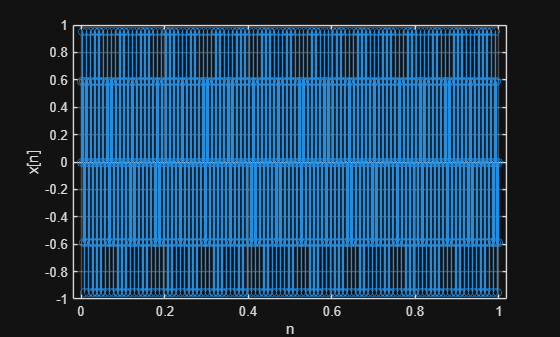

freq_hz = 100; % [hz]
freq_rads = 2*pi*freq_hz; % [rad/s]
freq_s = 1000; % [hz]
t_s = 1/freq_s; % [s]
t_0 = 0; % [s]
t_f = 1; % [s]
n = t_0:t_s:t_f; 
x = sin(freq_rads*n);
stem(n,x);
%plot(n, x);
xlabel('n');
ylabel('x[n]');
grid on;

### Ejercicio 2

snr = 10;
rng(0);
noisy_signal_myawgn = my_awgn(x, snr);
rng(0);
noisy_signal = awgn(x, snr,'measured');
mean_my_awgn = mean(noisy_signal_myawgn-x);
mean_awgn = mean(noisy_signal - x);
var_my_awgn = var(noisy_signal_myawgn - x);
var_awgn = var(noisy_signal-x);
snr1 = 10*log10(var(x)/var(noisy_signal_myawgn-x));
snr2 = 10*log10(var(x)/var(noisy_signal-x));
fprintf('Media del ruido \n');

Media del ruido 


fprintf('my_awgn: %.4f\n', mean_my_awgn);

my_awgn: -0.0071


fprintf('awgn:    %.4f\n\n', mean_awgn);

awgn:    -0.0071



fprintf('Varianza del ruido \n');

Varianza del ruido 


fprintf('my_awgn: %.4f\n', var_my_awgn);

my_awgn: 0.0498


fprintf('awgn:    %.4f\n\n', var_awgn);

awgn:    0.0498



fprintf('SNR estimado (dB)\n');

SNR estimado (dB)


fprintf('my_awgn: %.4f dB\n', snr1);

my_awgn: 10.0155 dB


fprintf('awgn:    %.4f dB\n', snr2);

awgn:    10.0155 dB


### Ejercicio 3

Deberia verse una amplificación de las frecuencias bajas y una respuesta en frecuencia que es la convolucion de la respuesta en frecuencia del escalon por un seno cardinal.

El bloque Zero-Order Hold esta trabajando a 150 Hz, muy por debajo de la frecuencia de muestreo de la señal, como mínimo, el bloque Zero Order debe filtrar a la misma frecuencia de muestreo de la señal que recibe.

### Ejercicio 4

El error se produce por la naturaleza de la señal y la capacidad del ADC de representar valores negativos.

Existen dos posibilidades, desfasar la señal a representar de tal manera que no tome valores negativos, aunque esto puede llegar a ser imposible dependiendo de la aplicación.

La otra opción es simplemente a nivel de software cambiar la media de la señal de tal manera que trabajamos solo con valores desde 0 (siendo este el valor mas bajo de la señal) hasta 2^(bits_res)-1 (valor mas bajo de la señal).

Luego de soluicionar ese problema, aparece un error inherente al proceso de representar una señal analogica como digital, el error de cuantización. La solución para reducir este valor a niveles lo suficientemente bajos para nuestra aplicación es elegir un adc con una resolución superior.

### Ejercicio 5

a. 

El nivel de quantización dado en voltios seria:

10V/(2^12-1)

quant = 10/(2^12-1)

quant = 0.0024

b.


$$SNR_{ADC} = 10 \log_{10}\Bigg(\frac{\sigma_x^2}{\sigma_e^2}\Bigg)=6.$$
 